# Time-Frequency Visualization: From Filter Banks to Welch, STFT and CWT

Pragmatic DSP Course | Live Script for lecture and self-study Learning outcomes: after this session you can (1) explain every spectral estimator as a bank of band-pass filters, (2) choose between Welch, STFT and CWT for a given signal, (3) read the time-frequency resolution trade-off from a plot, and (4) use the built-in MATLAB functions pwelch, spectrogram, pspectrum and cwt. Required toolboxes: Signal Processing Toolbox and Wavelet Toolbox. Run section by section (Ctrl+Enter) and change the parameters marked 'TRY THIS'.

clear; clc; close all
hasSPT = license('test','Signal_Toolbox');
hasWVT = license('test','Wavelet_Toolbox');
fprintf('Signal Processing Toolbox: %d | Wavelet Toolbox: %d\n', hasSPT, hasWVT);

Signal Processing Toolbox: 1 | Wavelet Toolbox: 1


## 1. The test signal

One signal that contains exactly the features each method treats differently. Sampling rate 2 kHz, duration 4 s. - Two stationary tones at 100 Hz and 120 Hz (close in frequency, needs good frequency resolution). - A linear chirp sweeping 250 Hz to 650 Hz (frequency changes with time). - A short 850 Hz tone burst at t = 1 s (localized in time, high frequency). - A click (almost an impulse) at t = 3 s (broadband, extremely short). - Weak white noise.

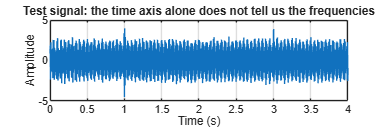

rng(0);
fs = 2000;  T = 4;
t  = (0:1/fs:T-1/fs)';  N = numel(t);

xTones = sin(2*pi*100*t) + sin(2*pi*120*t);
xChirp = 0.8*chirp(t, 250, T, 650, 'linear');
xBurst = 2*exp(-((t-1)/0.015).^2) .* sin(2*pi*850*(t-1));
xClick = 3*exp(-((t-3)/0.002).^2);
x = xTones + xChirp + xBurst + xClick + 0.1*randn(N,1);

figure('Position',[100 100 900 300])
plot(t, x); grid on; xlabel('Time (s)'); ylabel('Amplitude')
title('Test signal: the time axis alone does not tell us the frequencies')


% Question for the class: from this plot alone, can you tell the frequency of the chirp at t = 2 s? This is why we need time-frequency tools.

## 2. Starting point: the filter bank view

Every method in this lesson can be understood as the same machine: pass x(t) through many band-pass filters, each tuned to a centre frequency f_k, and look at how much energy comes out of each filter over time. The methods differ only in how the bandwidths are chosen. - Uniform filter bank: every filter has the same bandwidth. Frequency resolution is the same everywhere. This is the STFT (and, averaged over time, Welch). - Constant-Q filter bank: bandwidth is proportional to centre frequency, Q = f_c / bandwidth. Low frequencies get narrow filters (fine frequency resolution), high frequencies get wide filters (fine time resolution). This is the CWT. Below we build both banks with designfilt and look at their frequency responses. We deliberately use plain IIR band-pass filters so the idea is visible before any 'transform' name appears. ---- Uniform bank: bandwidth fixed at 40 Hz, centres every 20 Hz

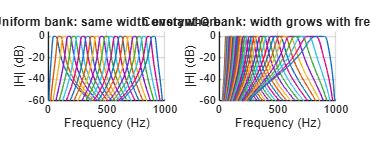

BW   = 40;
fcU  = 60:BW/2:900;
nU   = numel(fcU);
dU   = cell(nU,1);
envU = zeros(nU, N);
for k = 1:nU
    dU{k} = designfilt('bandpassiir','FilterOrder',6, ...
        'HalfPowerFrequency1',fcU(k)-BW/2, 'HalfPowerFrequency2',fcU(k)+BW/2, ...
        'SampleRate',fs);
    y = filtfilt(dU{k}, x);              % zero-phase filtering
    envU(k,:) = abs(hilbert(y)).';       % energy envelope of the filter output
end

% ---- Constant-Q bank: bandwidth = fc/Q
Q    = 6;
nQ   = 36;
fcQ  = logspace(log10(60), log10(850), nQ);
dQ   = cell(nQ,1);
envQ = zeros(nQ, N);
for k = 1:nQ
    bw = fcQ(k)/Q;
    dQ{k} = designfilt('bandpassiir','FilterOrder',6, ...
        'HalfPowerFrequency1',fcQ(k)-bw/2, 'HalfPowerFrequency2',fcQ(k)+bw/2, ...
        'SampleRate',fs);
    y = filtfilt(dQ{k}, x);
    envQ(k,:) = abs(hilbert(y)).';
end

figure('Position',[100 100 1000 380])
tiledlayout(1,2,'TileSpacing','compact')

nexttile; hold on
for k = 1:2:nU
    [h,f] = freqz(dU{k}, 4096, fs);
    plot(f, 20*log10(abs(h)+eps))
end
ylim([-60 5]); xlim([0 1000]); grid on
xlabel('Frequency (Hz)'); ylabel('|H| (dB)')
title('Uniform bank: same width everywhere')

nexttile; hold on
for k = 1:nQ
    [h,f] = freqz(dQ{k}, 4096, fs);
    plot(f, 20*log10(abs(h)+eps))
end
ylim([-60 5]); xlim([0 1000]); grid on
xlabel('Frequency (Hz)'); ylabel('|H| (dB)')
title('Constant-Q bank: width grows with frequency')

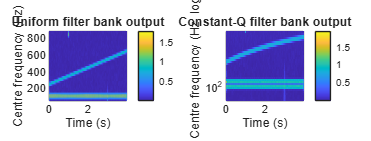


% Now the 'picture' of the signal is simply the filter-output envelopes stacked as an image: one row per filter, time along the x-axis.
figure('Position',[100 100 1000 380])
tiledlayout(1,2,'TileSpacing','compact')

nexttile
pcolor(t, fcU, envU); shading flat; colorbar
xlabel('Time (s)'); ylabel('Centre frequency (Hz)')
title('Uniform filter bank output')

nexttile
pcolor(t, fcQ, envQ); shading flat; colorbar
set(gca,'YScale','log')
xlabel('Time (s)'); ylabel('Centre frequency (Hz, log)')
title('Constant-Q filter bank output')


% Observe: in the uniform bank the two close tones (100 and 120 Hz) are separated better than in the constant-Q bank at the same place, and the click is smeared in time. In the constant-Q bank the 850 Hz burst and the click are sharp in time, while the low-frequency tones are well resolved in frequency on the log axis. Same data, different filter bandwidths, different picture.
% Everything that follows is a more efficient and better-behaved way of computing these two pictures.

## 3. Welch: averaged spectrum, no time axis

Welch's method cuts the signal into overlapping segments, windows each one, computes its periodogram, and averages them. Averaging reduces the variance of the estimate, but the time information is thrown away on purpose. In filter-bank language: Welch = uniform bank + average the output power over the whole record.

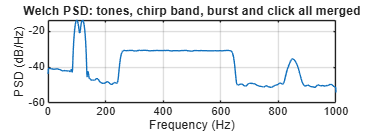

win = hann(256); nov = 128; nfft = 2048;
[pxx, f] = pwelch(x, win, nov, nfft, fs);

figure('Position',[100 100 900 320])
plot(f, 10*log10(pxx)); grid on
xlabel('Frequency (Hz)'); ylabel('PSD (dB/Hz)')
title('Welch PSD: tones, chirp band, burst and click all merged')

## 3.1 Welch is blind to time

If we reverse the signal in time, the chirp now sweeps downward and the events appear in the opposite order, yet the Welch estimate is almost identical.

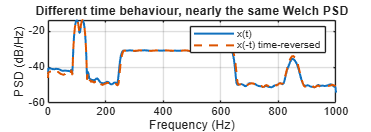

[pxxR, ~] = pwelch(flipud(x), win, nov, nfft, fs);

figure('Position',[100 100 900 320])
plot(f, 10*log10(pxx), 'LineWidth',1.5); hold on
plot(f, 10*log10(pxxR), '--', 'LineWidth',1.5); grid on
legend('x(t)','x(-t) time-reversed'); xlabel('Frequency (Hz)'); ylabel('PSD (dB/Hz)')
title('Different time behaviour, nearly the same Welch PSD')

## 3.2 Welch is the time-average of the STFT

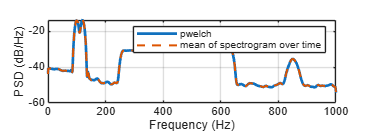

[S, fS, tS, PS] = spectrogram(x, win, nov, nfft, fs);   % PS = PSD of each segment
pAvg = mean(PS, 2);

figure('Position',[100 100 900 320])
plot(f, 10*log10(pxx), 'LineWidth',2); hold on
plot(fS, 10*log10(pAvg), '--', 'LineWidth',1.5); grid on
legend('pwelch','mean of spectrogram over time'); xlabel('Frequency (Hz)'); ylabel('PSD (dB/Hz)')

fprintf('Max difference between the two curves: %.3g\n', max(abs(pxx - pAvg)));

Max difference between the two curves: 2.08e-17


## 3.3 Resolution versus variance inside Welch

The segment length is the only knob. Long segments give fine frequency resolution but few averages (noisy curve). Short segments give a smooth curve but blur the two tones.

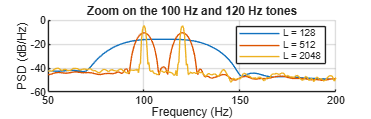

figure('Position',[100 100 1000 320]); hold on
for L = [128 512 2048]
    [p, ff] = pwelch(x, hann(L), round(L/2), 4096, fs);
    plot(ff, 10*log10(p), 'DisplayName', sprintf('L = %d', L))
end
grid on; legend; xlim([50 200]); xlabel('Frequency (Hz)'); ylabel('PSD (dB/Hz)')
title('Zoom on the 100 Hz and 120 Hz tones')


% TRY THIS: change the list of L and find the shortest segment that still separates the two tones.

## 4. STFT: a uniform filter bank that moves with time

The short-time Fourier transform slides a window w(t) along the signal and takes a Fourier transform of each piece: STFT(t, f) = integral of x(tau) w(tau - t) exp(-j 2 pi f tau) d tau Equivalent view: for each frequency f the STFT is the output of a band-pass filter whose impulse response is the window modulated to f. All filters share the same bandwidth, set by the window length. The spectrogram is `STFT`^2. The one-line version with automatic settings:

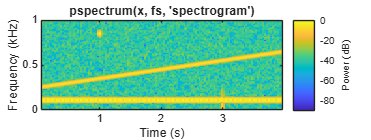

figure('Position',[100 100 900 340])
pspectrum(x, fs, 'spectrogram');
title('pspectrum(x, fs, ''spectrogram'')')

## 4.1 The window length decides everything

A short window localizes events in time but has poor frequency resolution. A long window does the opposite. This is the Heisenberg-Gabor uncertainty principle: time resolution times frequency resolution cannot be made arbitrarily small.

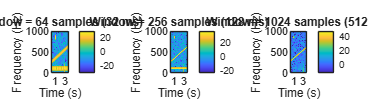

Ls   = [64 256 1024];
nfft = 2048;
figure('Position',[100 100 1200 360])
tiledlayout(1,3,'TileSpacing','compact')
for i = 1:3
    L = Ls(i);
    [s, fq, tq] = spectrogram(x, hann(L), round(0.9*L), nfft, fs);
    P = 10*log10(abs(s).^2 + eps);
    nexttile
    imagesc(tq, fq, P); axis xy
    set(gca,'CLim',[max(P(:))-60, max(P(:))]); colorbar
    xlabel('Time (s)'); ylabel('Frequency (Hz)')
    title(sprintf('Window = %d samples (%.0f ms)', L, 1000*L/fs))
end


% - L = 64: the click and the 850 Hz burst are sharp, but 100 Hz and 120 Hz merge into one thick band.
% - L = 256: a compromise.
% - L = 1024: the two tones separate cleanly, but the click and the burst are smeared over about half a second.
% Zero-padding (nfft larger than L) only interpolates the display. It does not improve the real resolution, which is fixed by L and the window shape.
% TRY THIS: replace hann with rectwin or kaiser(L,8) and compare leakage and main-lobe width.
% MATLAB also offers stft and istft (complex STFT with inverse, useful for filtering and reconstruction) and pspectrum with 'TimeResolution' to set the window by duration instead of samples.

## 5. CWT: a constant-Q filter bank

The continuous wavelet transform correlates the signal with scaled copies of a single mother wavelet psi: CWT(a, b) = (1/sqrt(a)) integral of x(t) conj(psi((t - b)/a)) dt Large scale a stretches the wavelet: long in time, narrow in frequency (low frequencies). Small scale a squeezes it: short in time, wide in frequency (high frequencies). The ratio centre frequency / bandwidth stays constant, so this is exactly the constant-Q bank from Section 2, built from one prototype. MATLAB exposes the filter bank directly through cwtfilterbank:

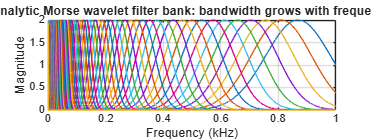

fb = cwtfilterbank('SignalLength', N, 'SamplingFrequency', fs);
figure('Position',[100 100 900 340])
freqz(fb)
title('Analytic Morse wavelet filter bank: bandwidth grows with frequency')

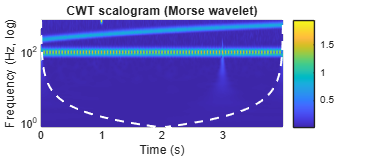


% Applying the bank to the signal gives the scalogram. The dashed line is the cone of influence (COI): below it, edge effects make the values unreliable.
[cfs, fCWT, coi] = wt(fb, x);

figure('Position',[100 100 900 380])
pcolor(t, fCWT, abs(cfs)); shading flat; colorbar
set(gca,'YScale','log'); hold on
plot(t, coi, 'w--', 'LineWidth',1.5)
ylim([min(fCWT) max(fCWT)])
xlabel('Time (s)'); ylabel('Frequency (Hz, log)')
title('CWT scalogram (Morse wavelet)')

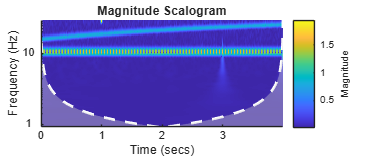


% The same result in one call: cwt(x, fs) plots the scalogram with the COI automatically.
figure('Position',[100 100 900 380])
cwt(x, fs);

## 5.1 The mother wavelet matters

Morlet ('amor') is Gaussian-shaped and good for time-frequency localization. Morse (default) has adjustable shape. Bump has narrower frequency support, so it separates close components better but is wider in time.

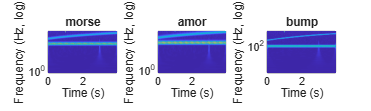

wnames = {'morse','amor','bump'};
figure('Position',[100 100 1200 360])
tiledlayout(1,3,'TileSpacing','compact')
for i = 1:3
    [c, ff] = cwt(x, wnames{i}, fs);
    nexttile
    pcolor(t, ff, abs(c)); shading flat
    set(gca,'YScale','log'); ylim([min(ff) max(ff)])
    xlabel('Time (s)'); ylabel('Frequency (Hz, log)')
    title(wnames{i})
end


% TRY THIS: pass 'VoicesPerOctave',24 to cwt for finer frequency sampling, or restrict 'FrequencyLimits' to zoom on the chirp.

## 6. Why the tiling differs: a picture to remember

Each rectangle is the area of the time-frequency plane that one coefficient 'sees'. The area is fixed by the uncertainty principle; only its shape changes.

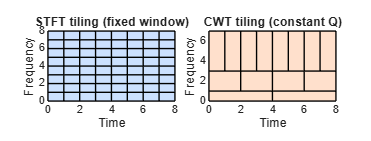

figure('Position',[100 100 1000 380])
tiledlayout(1,2,'TileSpacing','compact')

% STFT: all boxes identical
nexttile; hold on
for ix = 0:7
    for iy = 0:7
        rectangle('Position',[ix iy 1 1],'FaceColor',[0.80 0.88 1.0],'EdgeColor','k')
    end
end
axis([0 8 0 8]); xlabel('Time'); ylabel('Frequency'); title('STFT tiling (fixed window)')

% CWT: dyadic. Boxes get short and tall at high frequency
nexttile; hold on
y0 = [0 1 3];     % bottom of each octave band
hh = [1 2 4];     % bandwidth doubles every octave
ww = [4 2 1];     % duration halves every octave (same area per box)
for j = 1:3
    for ix = 0:ww(j):8-ww(j)
        rectangle('Position',[ix y0(j) ww(j) hh(j)],'FaceColor',[1.0 0.88 0.80],'EdgeColor','k')
    end
end
axis([0 8 0 7]); xlabel('Time'); ylabel('Frequency'); title('CWT tiling (constant Q)')

## 7. Side-by-side on the same signal

figure('Position',[100 100 1300 380])
tiledlayout(1,3,'TileSpacing','compact')

nexttile
plot(f, 10*log10(pxx)); grid on
xlabel('Frequency (Hz)'); ylabel('PSD (dB/Hz)'); title('Welch: frequency only')

nexttile
[s, fq, tq] = spectrogram(x, hann(256), 230, 2048, fs);
P = 10*log10(abs(s).^2 + eps);
imagesc(tq, fq, P); axis xy; set(gca,'CLim',[max(P(:))-60 max(P(:))])
xlabel('Time (s)'); ylabel('Frequency (Hz)'); title('STFT: fixed resolution')

nexttile
pcolor(t, fCWT, abs(cfs)); shading flat; set(gca,'YScale','log')
ylim([min(fCWT) max(fCWT)]); xlabel('Time (s)'); ylabel('Frequency (Hz, log)')
title('CWT: resolution adapts to frequency')

Method        = ["Welch";"STFT (spectrogram)";"CWT"];
FilterBank    = ["Uniform, averaged over time";"Uniform, bandwidth set by window";"Constant-Q, bandwidth proportional to f"];
TimeInfo      = ["None";"Yes, fixed resolution";"Yes, fine at high f, coarse at low f"];
FreqResolution= ["Set by segment length";"Set by window length";"Fine at low f, coarse at high f"];
FrequencyAxis = ["Linear";"Linear";"Logarithmic (octave based)"];
BestFor       = ["Stationary noise, PSD, vibration spectra";"Speech, chirps, slowly varying tones";"Transients, EEG/ECG events, signals with multiple scales"];
Functions     = ["pwelch";"spectrogram, stft, pspectrum";"cwt, cwtfilterbank"];
table(Method, FilterBank, TimeInfo, FreqResolution, FrequencyAxis, BestFor, Functions)

## 8. Choosing a method: quick rules

- Only the average frequency content matters and the signal is stationary: Welch. - Frequency changes slowly and you want a linear Hz axis (speech, radar, chirps): STFT, with the window matched to the fastest change you must follow. - Events of very different durations at different frequencies (clicks plus low rumble, biomedical bursts): CWT. - Need sharper ridges than either gives: look at fsst, wsst (synchrosqueezing), wvd (Wigner-Ville) and the Hilbert-Huang approach (emd, hht). They build on the same ideas.

## 9. Exercises

- Exercise 1: Change the chirp to sweep 250 Hz to 650 Hz in 0.5 s instead of 4 s. Which window length in the STFT still follows it? What happens in the CWT? - Exercise 2: Move the two tones to 100 Hz and 105 Hz. Find the minimum STFT window and the minimum Welch segment that resolves them. Relate your answer to delta f = 1 / (window duration). - Exercise 3: Replace the click by two clicks 5 ms apart. Which representation separates them, and why? - Exercise 4: In Section 2, set Q = 3 and Q = 12. Describe how the constant-Q picture moves toward the uniform one or the CWT one. - Exercise 5 (viva-style): Explain in three sentences why the Welch PSD of x(t) and of x(-t) are nearly equal while their spectrograms differ. - Exercise 6 (mini project): Load a real signal (audio with audioread, or ECG) and produce Welch, STFT and CWT figures. Justify your parameter choices in a short paragraph.